# Gráficos Renate

## NOTAS

% Este script permite crear gráficos a partir de la base de datos grande
% contenida en RenateData.csv, cuya estructura es idéntica a la de los
% datos en bruto una vez han sido importados. 

## Crear tabla a partir de la base de datos

% Importar base de datos
A = importRenatePlots("C:\Users\usuario\Desktop\Renate-files\RenateData.csv");

% Añadir la variable de fecha y quitar las variables de GPSDate y gpsTime
A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.Date = A.GPSDate + timeofday(A.gpsTime);
A.JulianDate = exceltime(A.Date);

A.GPSDate = [];
A.gpsTime = [];

% Hallar filas que dieron NaN y eliminarlas
noTime = find(isnan(A.JulianDate));
A(noTime, :) = [];

% Añadir las variables de presión en atm y quitar las variables en bares
A.licorPress2 = A.licorPress * 0.000986923;
A.atmPress2 = A.atmPress * 0.000986923;
A.equPress2 = A.equPress * 0.000986923;

A.licorPress = [];
A.atmPress = [];
A.equPress = [];

% Hacer NaN los valores de TEMP y SAL que son 0
A.TEMP = standardizeMissing(A.TEMP, 0);
A.SAL = standardizeMissing(A.SAL, 0);

% Encontrar valores nulos de temperatura
nullInt = find(isnan(A.IntakeTemp));
nullTSG = find(isnan(A.TEMP));
nullEqu = find(isnan(A.equTemp));
disp(numel(nullInt) + " Intake temperature values are NaN.");

271 Intake temperature values are NaN.


disp(numel(nullTSG) + " TSG temperature values are NaN.");

22904 TSG temperature values are NaN.


disp(numel(nullEqu) + " Equ temperature values are NaN.");

0 Equ temperature values are NaN.



% Encontrar valores erróneos de temperatura
badInt = find(A.IntakeTemp > 40 | A.IntakeTemp < 14);
badTSG = find(A.TEMP > 45 | A.TEMP < 10);
badEqu = find(A.equTemp > 45 | A.equTemp < 10);
disp("There are " + numel(badInt) + " wrong Intake Temperature values in " + numel(A.IntakeTemp) + " values.");

There are 3869 wrong Intake Temperature values in 123113 values.


disp("There are " + numel(badTSG) + " wrong TSG Temperature values in " + numel(A.TEMP) + " values.");

There are 24 wrong TSG Temperature values in 123113 values.


disp("There are " + numel(badEqu) + " wrong Equ Temperature values in " + numel(A.equTemp) + " values.");

There are 186 wrong Equ Temperature values in 123113 values.



% Convertir en NaN los valores erróneos de temperatura
A.IntakeTemp = standardizeMissing(A.IntakeTemp, A.IntakeTemp(badInt));
A.TEMP = standardizeMissing(A.TEMP, A.TEMP(badTSG));
A.equTemp = standardizeMissing(A.equTemp, A.equTemp(badEqu));
disp(numel(find(isnan(A.IntakeTemp))) + " Intake temperature values are now NaN.");

4140 Intake temperature values are now NaN.


disp(numel(find(isnan(A.TEMP))) + " TSG temperature values are now NaN.");

22928 TSG temperature values are now NaN.


disp(numel(find(isnan(A.equTemp))) + " Equ temperature values are now NaN.");

186 Equ temperature values are now NaN.



% Añadir las variables de diferencia de temperatura 
A.DiffEquInt = A.equTemp - A.IntakeTemp;
A.DiffTSGint = A.TEMP - A.IntakeTemp;
A.DiffEquTSG = A.equTemp - A.TEMP;

% Encontrar valores erróneos de salinidad y convertirlos en NaN. Hallar
% también valores NaN inicialmente
badSAL = find(A.SAL < 34);
nullSAL = find(isnan(A.SAL));
disp(numel(nullSAL) + " Salinity values are NaN.");

22942 Salinity values are NaN.


disp("There are " + numel(badSAL) + " wrong salinity values in " + numel(A.SAL) + " values.");

There are 56 wrong salinity values in 123113 values.


A.SAL = standardizeMissing(A.SAL, A.SAL(badSAL));
disp(numel(find(isnan(A.SAL))) + " salinity values are now NaN.");

22998 salinity values are now NaN.



% Encontrar valores erróneos de presión atmosférica y convertirlos en NaN.
% Hallar también valores NaN iniciales
badPress = find(A.atmPress2 < 0.9);
nullPress = find(isnan(A.atmPress2));
disp(numel(nullPress) + " atm pressure values are NaN.");

0 atm pressure values are NaN.


disp("There are " + numel(badPress) + " wrong pressure values in " + numel(A.atmPress2) + " values.");

There are 95 wrong pressure values in 123113 values.


A.atmPress2 = standardizeMissing(A.atmPress2, A.atmPress2(badPress));
disp(numel(find(isnan(A.atmPress2))) + " pressure values are now NaN.");

95 pressure values are now NaN.



% Encontrar valores erróneos de flujo de agua en el equilibrador y convertirlos en NaN.
% Hallar también valores NaN iniciales
badH2O = find(A.H2OFlow < 2.5);
nullH2O = find(isnan(A.H2OFlow));
disp(numel(nullH2O) + " H2O flow values are NaN.");

0 H2O flow values are NaN.


disp("There are " + numel(badH2O) + " wrong pressure values in " + numel(A.H2OFlow) + " values.");

There are 20544 wrong pressure values in 123113 values.


A.H2OFlow = standardizeMissing(A.H2OFlow, A.H2OFlow(badH2O));
disp(numel(find(isnan(A.H2OFlow))) + " H2O flow values are now NaN.");

20544 H2O flow values are now NaN.


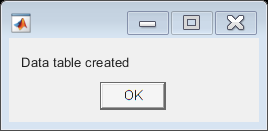


% Recolocar las columnas en la tabla
A = movevars(A, ["DiffEquInt" "DiffTSGint", "DiffEquTSG"], "After", "Temp");
A = movevars(A, ["Date", "JulianDate"], "After", "Type");

% Ordenar las filas por fecha
A = sortrows(A, "Date");

msgbox("Data table created");

## Representar las distintas variables

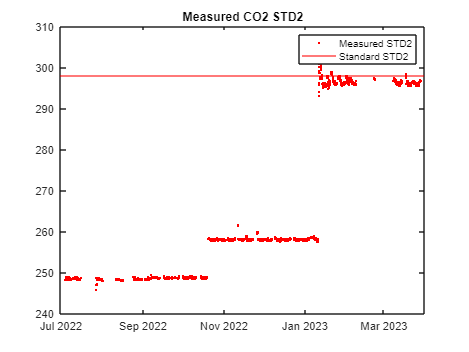

% Representar los valores medidos de los gases con su valor estándar
plot(A.Date(A.Type == "STD2"), A.CO2Umm(A.Type == "STD2"), ".r") % Gas 2
hold on
yline(298.06, 'r')
hold off
title("Measured CO2 STD2")
legend("Measured STD2", "Standard STD2", "Location", "northeast")

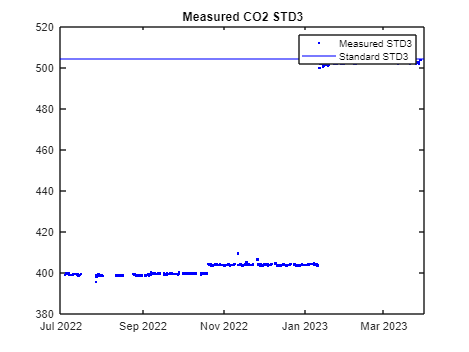


plot(A.Date(A.Type == "STD3"), A.CO2Umm(A.Type == "STD3"), ".b") % Gas 3
hold on
yline(504.32, 'b')
hold off
title("Measured CO2 STD3")
legend("Measured STD3", "Standard STD3", "Location", "northeast")

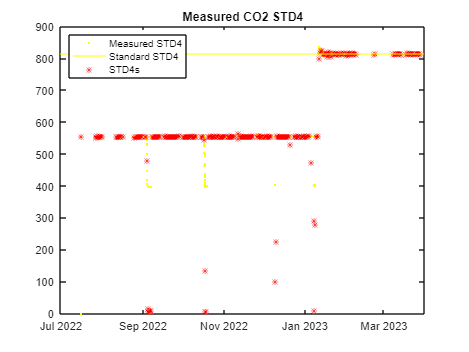


plot(A.Date(A.Type == "STD4"), A.CO2Umm(A.Type == "STD4"), ".y") % Gas 4
hold on
yline(813.27, 'y')
hold on
plot(A.Date(A.Type == "STD4s"), A.CO2Umm(A.Type == "STD4s"), "*r")
hold off
title("Measured CO2 STD4")
legend("Measured STD4", "Standard STD4", "STD4s", "Location", "northwest")

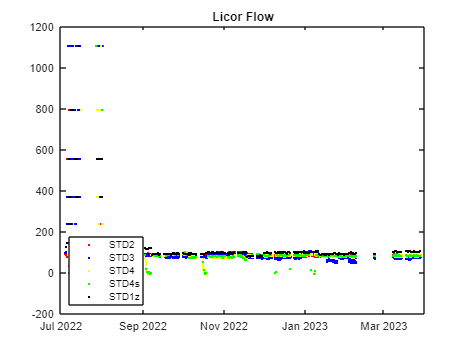



% Representar licor flow de los gases y de las mediciones atmosféricas y
% equilibrador
plot(A.Date(A.Type == "STD2"), A.licorFlow(A.Type == "STD2"), ".r") 
hold on
plot(A.Date(A.Type == "STD3"), A.licorFlow(A.Type == "STD3"), ".b")
hold on
plot(A.Date(A.Type == "STD4"), A.licorFlow(A.Type == "STD4"), ".y")
hold on
plot(A.Date(A.Type == "STD4s"), A.licorFlow(A.Type == "STD4s"), ".g")
hold on
plot(A.Date(A.Type == "STD1z"), A.licorFlow(A.Type == "STD1z"), ".k")
hold off
title("Licor Flow")
legend("STD2", "STD3", "STD4", "STD4s", "STD1z", "Location", "southwest")

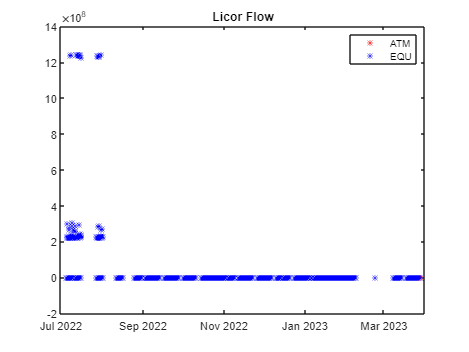


plot(A.Date(A.Type == "ATM"), A.licorFlow(A.Type == "ATM"), "*r")
hold on
plot(A.Date(A.Type == "EQU"), A.licorFlow(A.Type == "EQU"), "*b")
hold off
title("Licor Flow")
legend("ATM", "EQU")

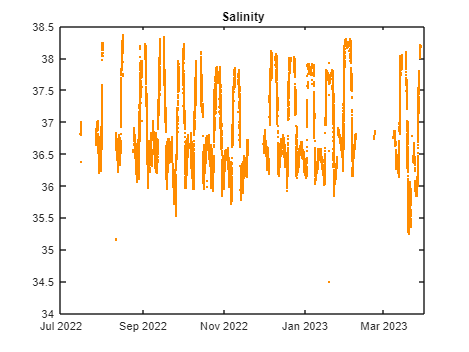

    

% Salinidad
plot(A.Date, A.SAL, ".", "Color", "#FF8C00")
title("Salinity")

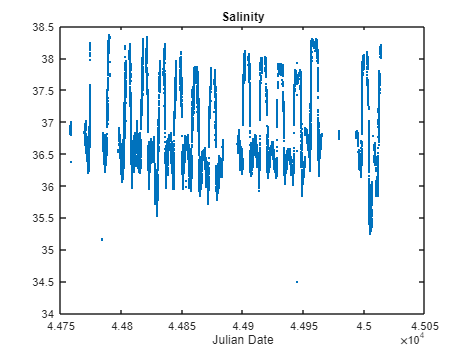

%ylim([35 39])

plot(A.JulianDate, A.SAL, ".")
title("Salinity")
xlabel("Julian Date")

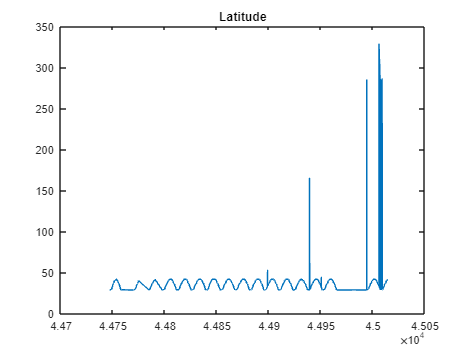

%ylim([35 39])


% Coordenadas
plot(A.JulianDate, A.latitude)
title("Latitude")

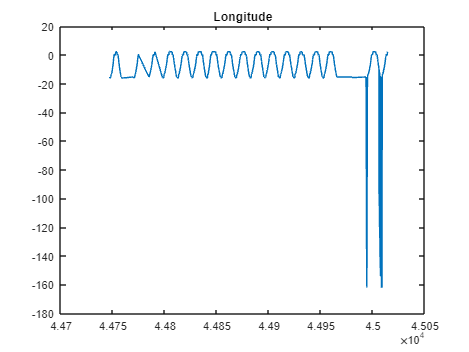


plot(A.JulianDate, A.longitude)
title("Longitude")

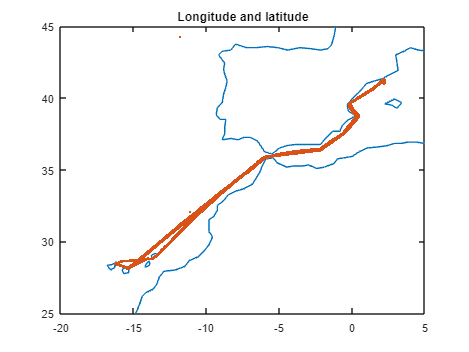


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

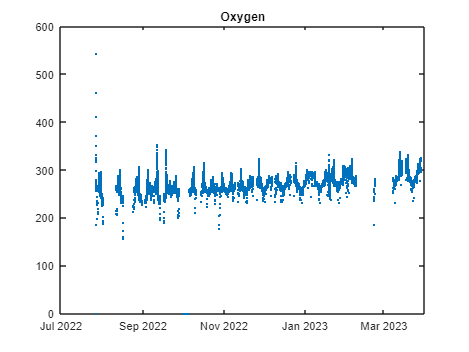



% Oxígeno
plot(A.Date, A.Oxygen, ".")
title("Oxygen")

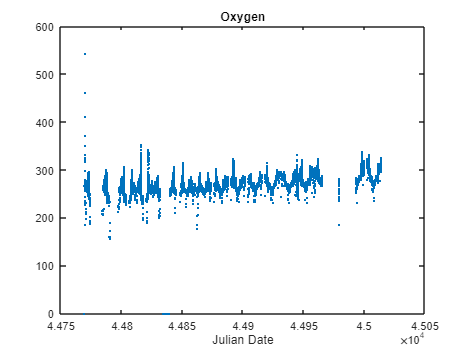

%ylim([200 350])

plot(A.JulianDate, A.Oxygen, ".")
title("Oxygen")
xlabel("Julian Date")

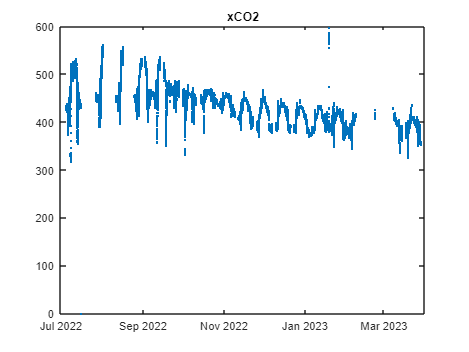

%ylim([200 350])


% xCO2 en el equilibrador
plot(A.Date(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")

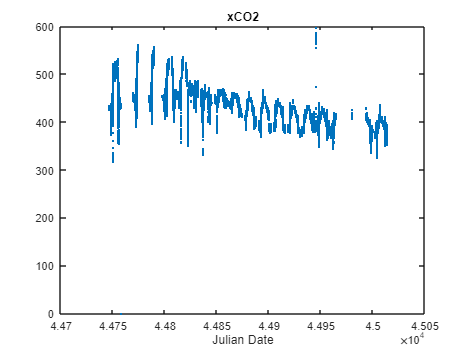

% ylim([350 550])

plot(A.JulianDate(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")
xlabel("Julian Date")

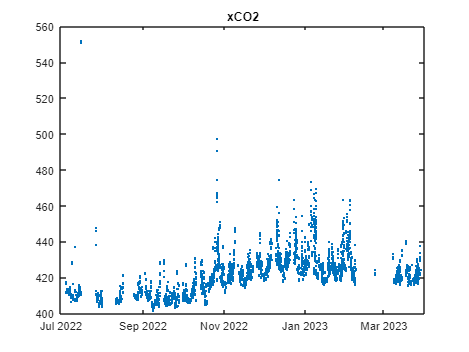

% ylim([350 550])


% xCO2 atmosférico
plot(A.Date(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2")

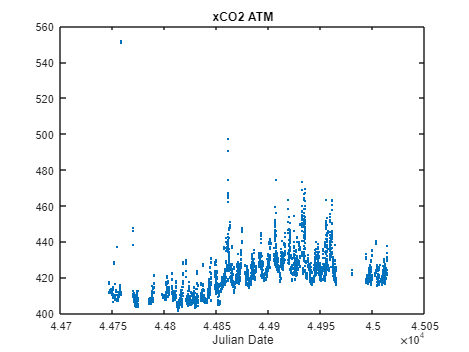

% ylim([350 550])

plot(A.JulianDate(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2 ATM")
xlabel("Julian Date")

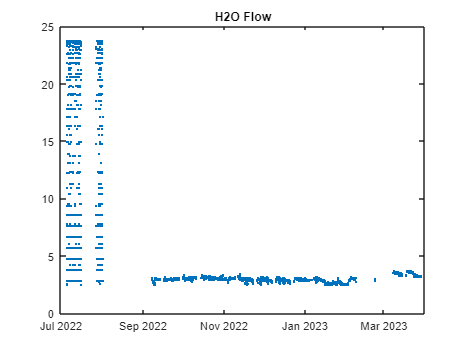

% ylim([350 550])


% Flujo de agua en el equilibrador
plot(A.Date(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
% ylim([-0.5, 3.5])
title("H2O Flow")

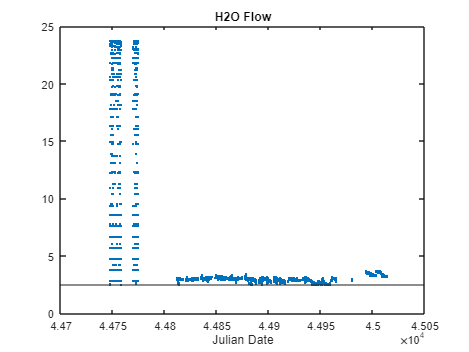

%ylim([0, 3.8])

plot(A.JulianDate(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
hold on
yline(2.5)
hold off
% ylim([-0.5, 3.5])
title("H2O Flow")
xlabel("Julian Date")

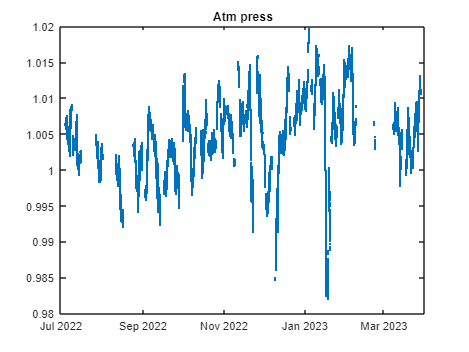



% Presiones

% Atm press
plot(A.Date, A.atmPress2, ".")
title("Atm press")

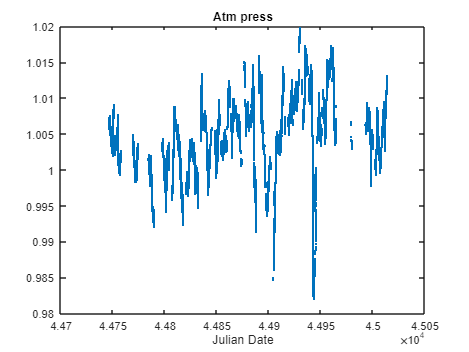

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
title("Atm press")
xlabel("Julian Date")

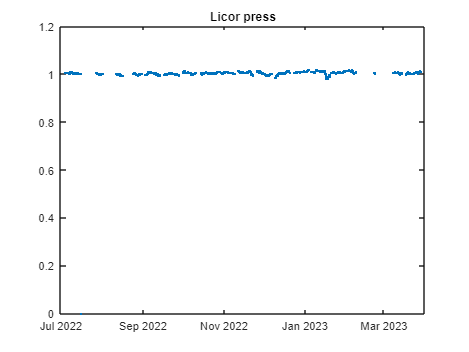

%ylim([0.97 1.03])

% Licor Press
plot(A.Date, A.licorPress2, ".")
title("Licor press")

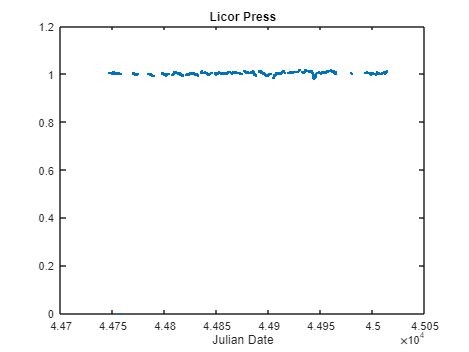


plot(A.JulianDate, A.licorPress2, ".")
title("Licor Press")
xlabel("Julian Date")

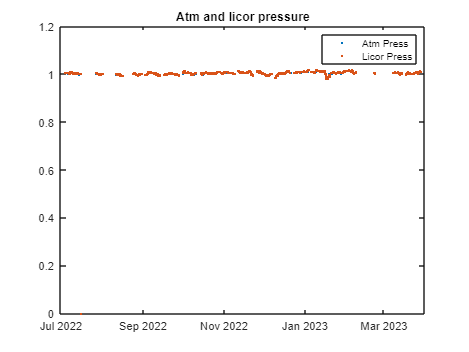


% Juntas
plot(A.Date, A.atmPress2, ".")
hold on
plot(A.Date, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")

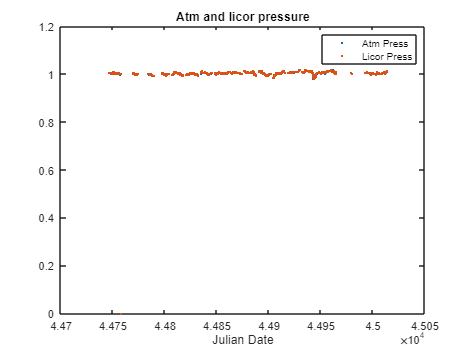

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
hold on
plot(A.JulianDate, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")
xlabel("Julian Date")

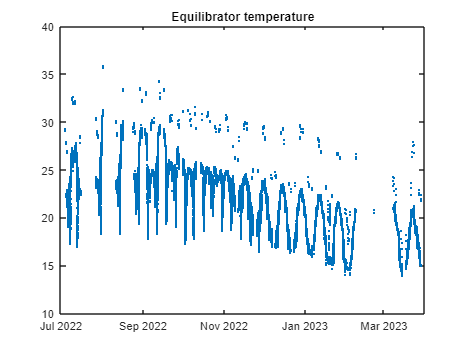

%ylim([0.97 1.03])


% Temperaturas

% Equ Temp
plot(A.Date, A.equTemp, ".")
title("Equilibrator temperature")

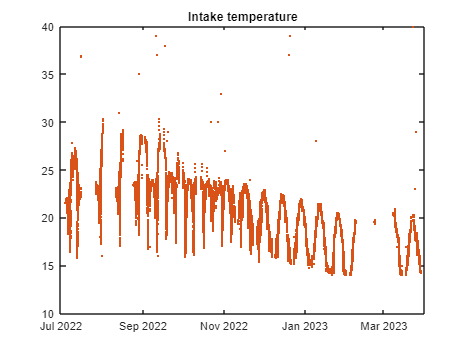

%ylim([14 32])

% Intake temp
plot(A.Date, A.IntakeTemp, ".", "Color", "#D95319")
title("Intake temperature")

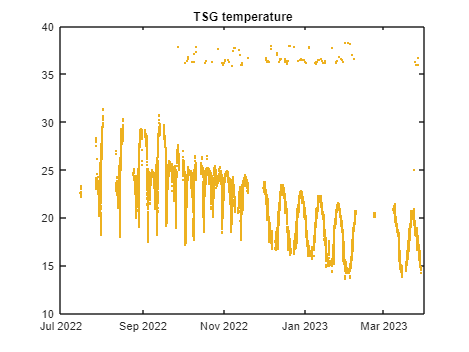

%ylim([11 24])
% A veces da valores de miles que habría que quitar

% TSG temp
plot(A.Date, A.TEMP, ".", "Color", 	"#EDB120")
title("TSG temperature")

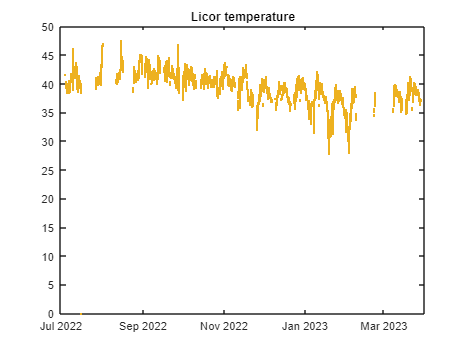

%ylim([14 30])
% A veces da valores de miles que habría que quitar 

% Licor temp
plot(A.Date, A.licorTemp, ".", "Color", "#EDB120")
title("Licor temperature")

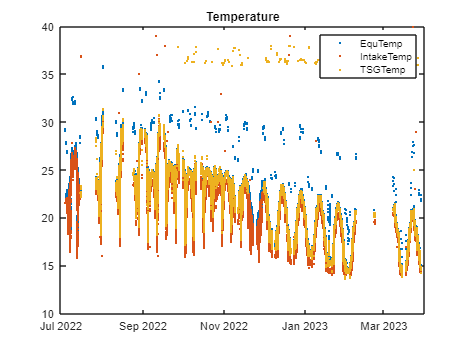

% ylim([14 30])

% Todas juntas menos licor temp
plot(A.Date, A.equTemp, ".")
hold on
plot(A.Date, A.IntakeTemp, ".")
hold on
plot(A.Date, A.TEMP, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")

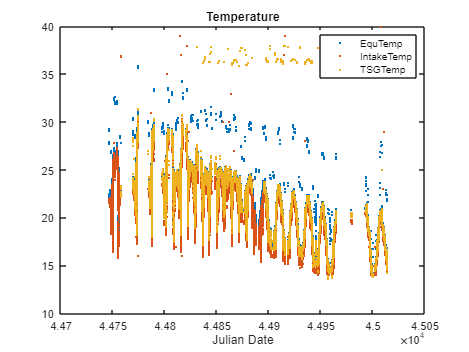

% ylim([15 24])
%ylim([12 32])

plot(A.JulianDate, A.equTemp, ".")
hold on
plot(A.JulianDate, A.IntakeTemp, ".")
hold on
plot(A.JulianDate, A.TEMP, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")
% ylim([15 30])
xlabel("Julian Date")

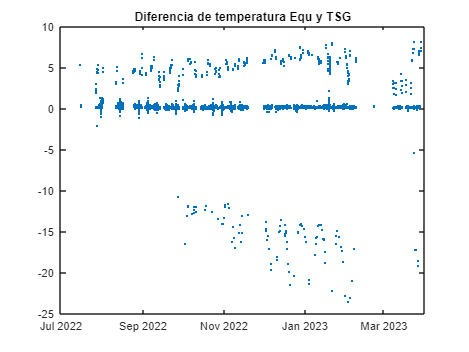

%ylim([12 32])


% Diferencias de temperatura

% Equ y TSG
plot(A.Date, A.DiffEquTSG, ".")
title("Diferencia de temperatura Equ y TSG")

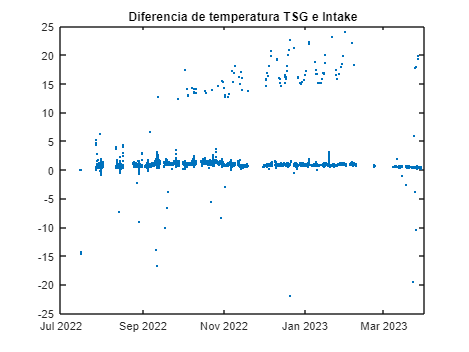

%ylim([-0.5 2.5])

% TSG e Intake
plot(A.Date, A.DiffTSGint, ".")
title("Diferencia de temperatura TSG e Intake")

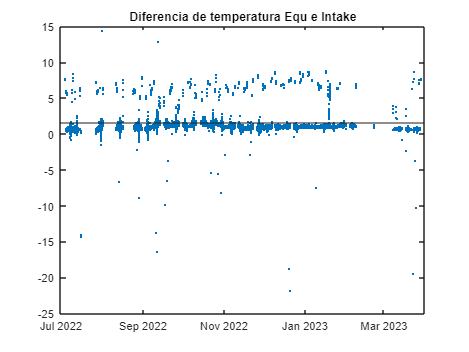

%ylim([0 2])

% Equ e Intake
plot(A.Date, A.DiffEquInt, ".")
title("Diferencia de temperatura Equ e Intake")
%ylim([0 2])
hold on
yline(1.5)
hold off

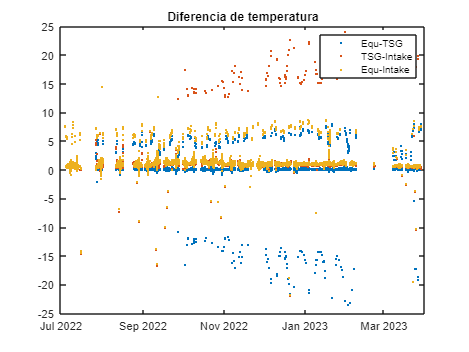


% Juntas 
plot(A.Date, A.DiffEquTSG, ".")
hold on
plot(A.Date, A.DiffTSGint, ".")
hold on
plot(A.Date, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")

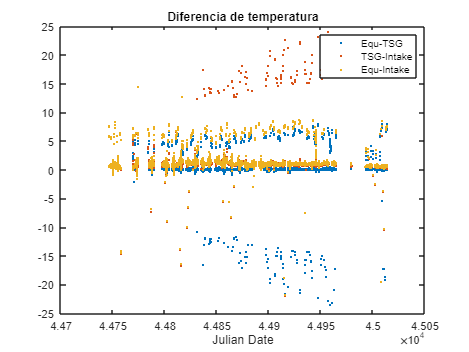

%ylim([-0.5 2])

plot(A.JulianDate, A.DiffEquTSG, ".")
hold on
plot(A.JulianDate, A.DiffTSGint, ".")
hold on
plot(A.JulianDate, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")
xlabel("Julian Date")

%ylim([-0.5 2])